N=1000

N = 1000

n=4

n = 4

ea=randn(N,1);

theta=[0.5 0.6 0.3 0.5]

theta =     0.5000    0.6000    0.3000    0.5000


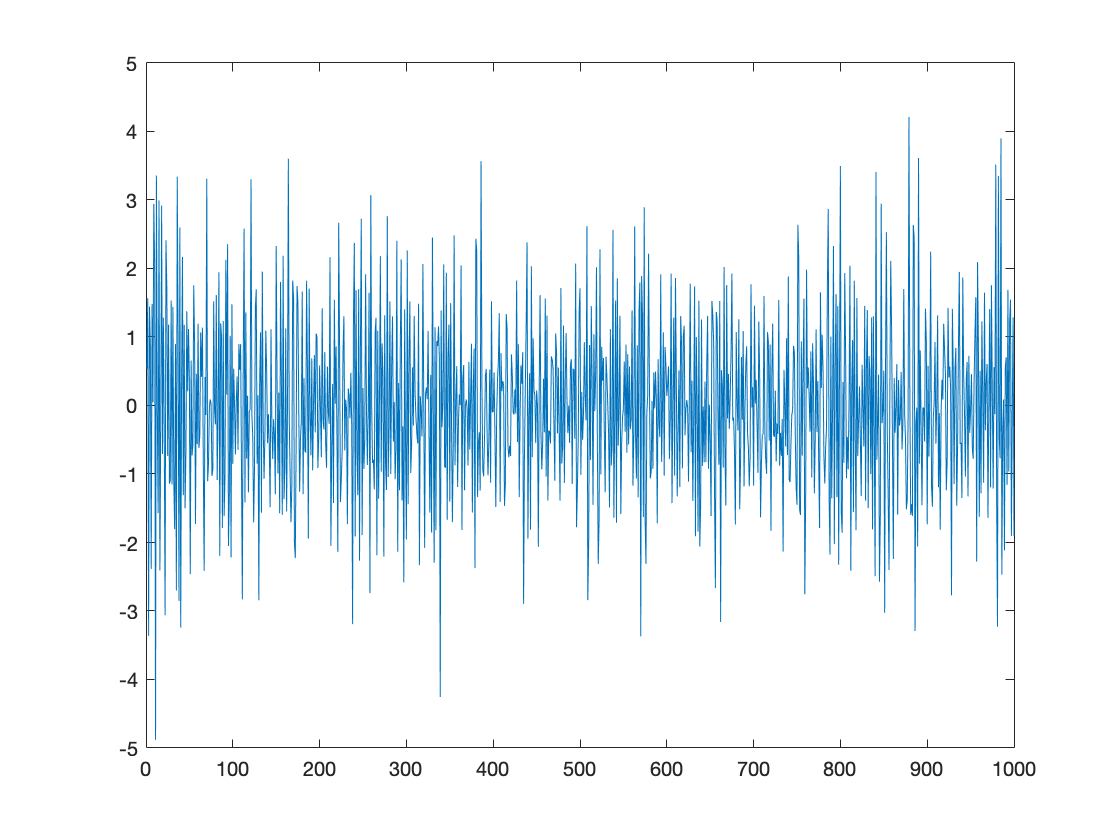


ya(1)= ea(1);
ya(2)=-0.5*ya(1)+ea(2);
ya(3)=-0.5*ya(2) -0.6*ya(1) +ea(3);
ya(4)=-0.5*ya(3) -0.6*ya(2)- 0.3*ya(1) +ea(4);
ya(5)=-0.5*ya(4) -0.6*ya(3)- 0.3*ya(2) -0.5*ya(1) +ea(5);

for t=6:N
    ya(t)=-0.5*ya(t-1) -0.6*ya(t-2)- 0.3*ya(t-3) -0.5*ya(t-4) +ea(t);
    
end

plot(ya)

%Levinson algorithm

%
% Levinson algorithm.
%
% The matrix a is lower triangular of size nxn, and contains the
% estimated AR models of orders 1 to n that the Levinson algorithm
% comes across.
% The vector v contains the corresponding estimates of the
% (forward) prediction error variances, running from 0 to n.
% The vector rho contains the n reflection coefficients.
%


z=ya(:);
m=size(z,1);
for i=0:n
   r(i+1)=z(1:m-i).'*z(1+i:m)/(m-i);
end
v(1)=r(1);
for i=1:n
   alpha(i)=r(i+1);
   for j=1:i-1
      alpha(i)=alpha(i)+a(i-1,j)*r(i+1-j);
   end
   rho(i)=-alpha(i)/v(i);
   v(i+1)=v(i)*(1-rho(i)^2);
   a(i,i)=rho(i);
   for j=1:i-1
      a(i,j)=a(i-1,j)+rho(i)*a(i-1,i-j);
   end
end


%using the parameters learned

ys(1)= ea(1);
ys(2)=-a(4,1)*ys(1)+ea(2);
ys(3)=-a(4,1)*ys(2) -a(4,2)*ys(1) +ea(3);
ys(4)=-a(4,1)*ys(3) -a(4,2)*ys(2)-a(4,3)*ys(1) +ea(4);
ys(5)=-a(4,1)*ys(4) -a(4,2)*ys(3)-a(4,3)*ys(2) -a(4,4)*ys(1) +ea(5);

for t=6:N
    ys(t)=-a(4,1)*ys(t-1) -a(4,2)*ys(t-2)-a(4,3)*ys(t-3) -a(4,4)*ys(t-4) +ea(t);
    
end

NMSE = sum((ya-ys).^2)/sum(ya.^2)

NMSE = 0.0096

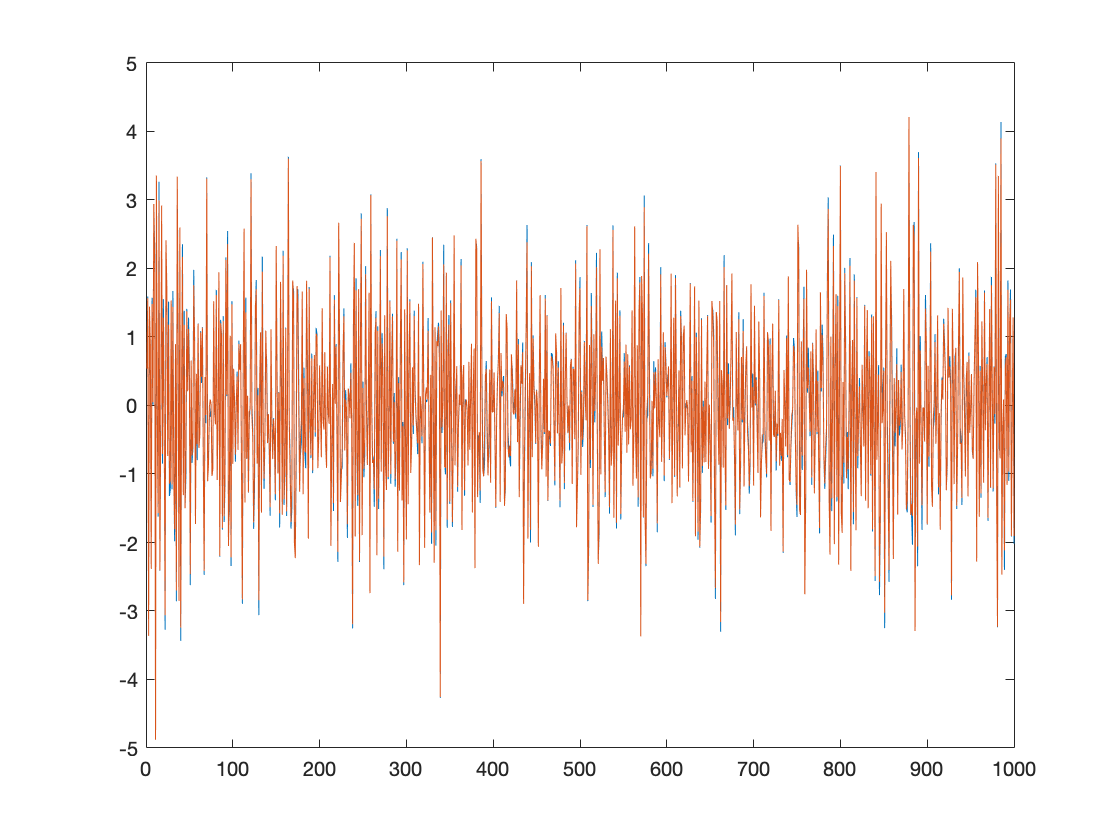


plot(ys)
hold on
plot(ya)

%using the data in the file resuing variables because of lazyness
largestorder=20

largestorder = 20

n = 20

n = 20


m = length(y)

Undefined function or variable 'y'.



z=y(:);
m=size(z,1);
for i=0:n
   r(i+1)=z(1:m-i).'*z(1+i:m)/(m-i);
end
v(1)=r(1);
for i=1:n
   alpha(i)=r(i+1);
   for j=1:i-1
      alpha(i)=alpha(i)+a(i-1,j)*r(i+1-j);
   end
   rho(i)=-alpha(i)/v(i);
   v(i+1)=v(i)*(1-rho(i)^2);
   a(i,i)=rho(i);
   for j=1:i-1
      a(i,j)=a(i-1,j)+rho(i)*a(i-1,i-j);
   end
end


for n = 1:largestorder
    clear ys
    ys = zeros(1,m);
    ys(1:n) = e(1:n);
    for i = n+1:m
        ys(i) = a(n,1:n)*(-ys(i-1:-1:i-n))'+e(i);
    end
    ys=ys';
    NMSE(n) = sum ((y-ys).^2)/sum(y.^2);
    sigma2 = 1/(m-n) * sum((y-ys).^2);
    AIC(n)=m*log(sigma2) + 2*(n+1);
end

[mm,indm]=min(NMSE)